# Project 1 Baseband Channel

**Objective**: To simulate 4-ary communication and fading channels. In each case, observe the sent and received symbol values and measure bit errors. (Suggested package is MATLAB.) 

### Part 1: 4-ary Channel

Generate an equally probable random sequence of 1’s and 0’s of length 200,000 or more. In other words, the a priori probabilities, i.e., the probability of sending a 1 or a 0 are: Pr[0s] = Pr[1s] = 0.5. Now obtain the QPSK symbols, i.e., form the 2-bit groups as follows: {A = ‘00’, B = ‘01’, C = ‘11’, D = ‘10’}.  

% Generate an array of random bits using a binomial distribution generator
n = 1;  p = 0.5; l = 200000; 
msg_bits = binornd(n, p, 1, l);
% Create QPSK Symbol list
slist = string(zeros(1, l/2));sbinlist = string(zeros(1, l/2));
binmap = containers.Map; smap = containers.Map;
binmap('00') = 'A'; binmap('01') = 'B'; binmap('11') = 'C'; binmap('10') = 'D';
smap('A') = '00'; smap('B') = '01'; smap('C') = '11'; smap('D') = '10';
for i = 1:2:200000
    s = string(msg_bits(i)) + string(msg_bits(i+1));
    sbinlist((i+1)/2) = s;
    slist((i+1)/2) = binmap(s);
end

Consider a symmetric 4-ary communications channel with Pr[XR|XS] = 0.99 where XR and XS are the received and sent symbol values {A, B, C, D}.  Input the QPSK symbols to the 4-ary channel and record the output symbols, de-map them to bits.

rlist = string(zeros(1, l/2));
rbinlist = string(zeros(1, l/2)); 
for k = 1:l/2
    x = slist(k);
    [rlist(k), rbinlist(k)] = fouraryChannel(x, smap, binmap);
end

%Calculate the bit error
badbits = 0;
for i = 1:l/2
    r = rbinlist(i); s = sbinlist(i);
    if r ~= s
        badbits = badbits + 1;
    end
end

biterror = double(badbits/(l/2)); 
disp('Bit Error: '+string(biterror*100) + '%')

Bit Error: 1.964%


### Part 2: Fading Channel

%create the constellation mapping from binary sequence rbinlist
constellationMap = containers.Map


constellationMap = 

  Map with properties:

        Count: 0
      KeyType: char
    ValueType: any



constellationMap('A') = 1; constellationMap('B') = 1i; constellationMap('C') = -1; constellationMap('D') = -1i;
[cmplxlist, ltrlist] = binToSymbols(sbinlist, binmap, constellationMap);

%ToDo: Make the channel and feed it cmplxlist

sigma = 0.1; 
a_mag = raylrnd(sigma, [1, l/2]);   %create the complex coefficient 'a' using a rayleigh distribution
theta = (2*pi).*rand([1, l/2]);     %create theta based on uniform distribution
expTheta = exp(-1j.*theta);
a_vec = a_mag .* expTheta;     % enumerate the a values in a list
t_symbol = 1e-6;                    % enumerate the sample periods 
t = (t_symbol: t_symbol:l/2*t_symbol); 

y = fadeChannel(cmplxlist, a_vec);

## Plotting Results

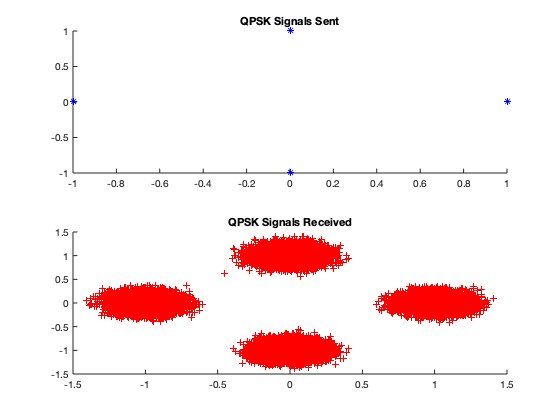


tiledlayout(2, 1)
nexttile
scatter(real(cmplxlist), imag(cmplxlist), "blue", '*')
title('QPSK Signals Sent'); 

nexttile
scatter(real(y), imag(y), "red", '+')
title('QPSK Signals Received'); 

hold off; 

## Calculating Bit Error

rec_symbols = [real(y); imag(y)];
qpsks = [1, 0;0, 1; -1, 0;0, -1];
req_qpsk = knnsearch(qpsks, rec_symbols');
tic
req_qpsk_bin=zeros(1,200000)

req_qpsk_bin =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


w=1;
for i=1:length(req_qpsk)
    if req_qpsk(i) == 1
        req_qpsk_bin(w) = 0;
        req_qpsk_bin(w+1)=0;
    elseif req_qpsk(i) == 2
        req_qpsk_bin(w) = 0;
        req_qpsk_bin(w+1)=1;
    elseif req_qpsk(i) == 3
        req_qpsk_bin(w) = 1;
        req_qpsk_bin(w+1)=1;
    else
        req_qpsk_bin(w) = 1;
        req_qpsk_bin(w+1)=0;
    end
    w=w+2;
end
toc

Elapsed time is 1.349489 seconds.


cmp = req_qpsk_bin==msg_bits;
correct = sum(cmp);
per_cor = ((correct)/200000);
per_error = 1-per_cor;

function [y, ybin] = fouraryChannel(x, smap, binmap)   % x is a symbol: [A, B, C, D]
    binVal = smap(x);           
    i = randi([0,100]);
    if i <= 98
        y = x;
        ybin = binVal; 
        return
    end
    j = mod(i, 2) + 1 ;  % determine which bit gets flipped; assumes equiprob bit err
    if binVal(j) == '1'
        binVal(j) = '0';
    else
        binVal(j) = '1';
    end
    y = binmap(binVal);
    ybin = binVal;
    return
end

function [cmplxlist, ltrlist] = binToSymbols(xarr, binmap, cmap)
    ylen = length(xarr); 
    cmplxlist = zeros(1, ylen);
    ltrlist = string(zeros(1, ylen));
    for n = 1:1:ylen
        s = xarr(n);
        ltrlist(n) = binmap(s);
        cmplxlist(n) = cmap(binmap(s));
    end
end

function y = fadeChannel(xarr, as)
    xlen = length(xarr);
    y = zeros([1, xlen]); 
    y(1) = xarr(1); 
    for n = 2:1:xlen
        y(n) = xarr(n) + as(n).*xarr(n-1); 
    end
end